pathA = 'https://i.ibb.co/gVtt8dV/Q4-Image-1.jpg';
pathB = 'https://i.ibb.co/8BgvmWh/Q4-image-2.jpg';
image1  = imread(pathA);
image2  = imread(pathB);

grayScaleImage1 = rgb2gray(image1);
grayScaleImage2 = rgb2gray(image2);

FtOfImage1 = fft2(grayScaleImage1);
FtOfImage2 = fft2(grayScaleImage2);


% magnitude only part of image 1 
magnitude = abs(fftshift(FtOfImage1));
%imshow(log(1+(abs(fftshift(FtOfImage1)))),[],'InitialMagnification','fit')

%reconstructing image1 from magnitude
ReConstMag = ifft2(magnitude*exp(1i*0));

% phase only part of image 1
phase = angle(FtOfImage1);
%imshow(log(1+phase),[],'InitialMagnification','fit')

%reconstructing image 1 from phase 
ReConstPhase = ifft2(1*exp(1i*phase));

% displaying image 1 
subplot(1,3,1),imshow(grayScaleImage1),title('image A');
subplot(1,3,2),imshow(ReConstMag,[],'InitialMagnification','fit'),title('magnitude reconstruction');

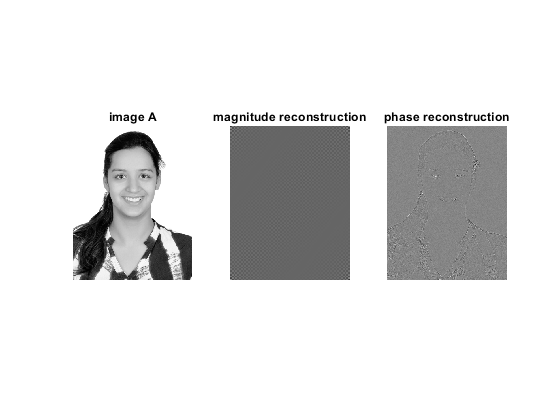

subplot(1,3,3),imshow(ReConstPhase,[],'InitialMagnification','fit'),title('phase reconstruction');

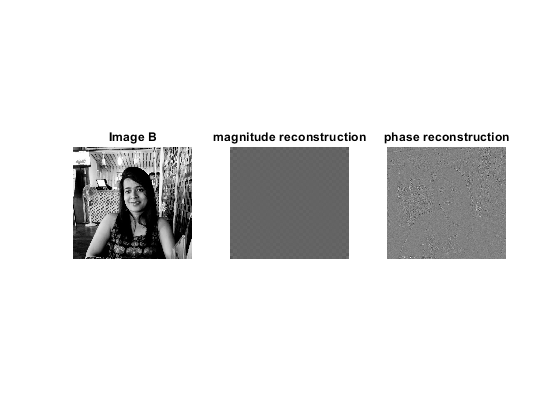

% magnitude only part of image 2 
magnitude2 = abs(fftshift(FtOfImage2));
%imshow(log(1+(abs(fftshift(FtOfImage2)))),[],'InitialMagnification','fit')

%reconstructing image2 from magnitude
ReConstMag2 = ifft2(magnitude2*exp(1i*0));

% phase only part of image 2
phase2 = angle(FtOfImage2);

%reconstructing image 1 from phase 
ReConstPhase2 = ifft2(1*exp(1i*phase2));

% displaying image 1 
subplot(1,3,1),imshow(grayScaleImage2),title('Image B');
subplot(1,3,2),imshow(ReConstMag2,[],'InitialMagnification','fit'),title('magnitude reconstruction');
subplot(1,3,3),imshow(ReConstPhase2,[],'InitialMagnification','fit'),title('phase reconstruction');

% taking magnitude of image 1 and phase of image 2
% taking fft after making the size same

grayScaleImage1 = rgb2gray(image1);
grayScaleImage2 = rgb2gray(image2);

[r1,c1] = size(grayScaleImage1);
[r2,c2] = size(grayScaleImage1);
rmax = max(r1, r2);
cmax = max(c1, c2);
FFtofImage1 = fft2(grayScaleImage1,rmax,cmax);
FFtofImage2 = fft2(grayScaleImage2,rmax,cmax);


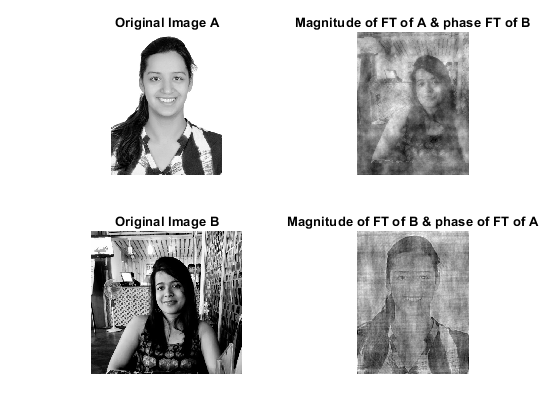

magnitudeOfImage1 = abs(FFtofImage1);
phaseOfImage2 = angle(FFtofImage2);
ReconstructedImageA = ifft2(magnitudeOfImage1.*exp(1i*phaseOfImage2));
figure;
subplot(2,2,1),imshow(grayScaleImage1),title('Original Image A');
subplot(2,2,2),imshow(ReconstructedImageA,[],'InitialMagnification','fit'),title('Magnitude of FT of A & phase FT of B')

magnitudeOfImage2 = abs(FFtofImage2);
phaseOfImage1 = angle(FFtofImage1);

ReconstructedImageB = ifft2(magnitudeOfImage2.*exp(1i*phaseOfImage1));
subplot(2,2,3),imshow(grayScaleImage2),title('Original Image B');
subplot(2,2,4),imshow(ReconstructedImageB,[],'InitialMagnification','fit'),title('Magnitude of FT of B & phase of FT of A')